dt=1/1000;
t = 0:dt:0.5;
u1 = sin(2*pi*50*t);
u2 = sin(2*pi*100*t);
u3 = 0*sin(2*pi*75*t);

u = u1+u2+u3;
M=300;
H = hankel(u(1:M),u(M:end));

[U,S,V]=svd(H);

rr=rank(H)

rr = 4

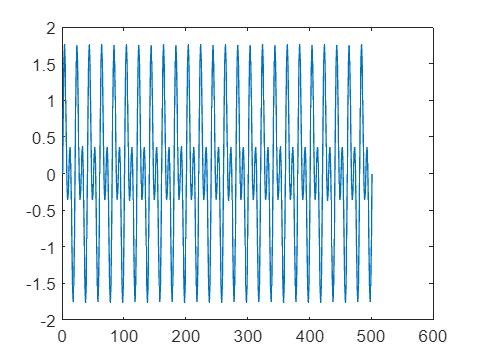

figure; plot(u)

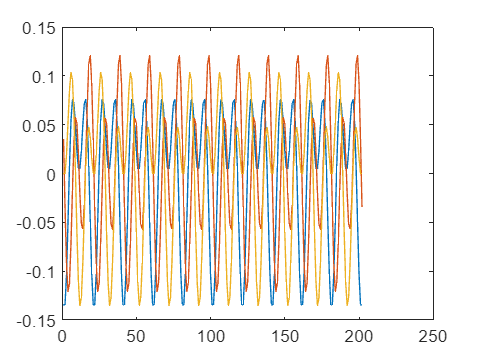

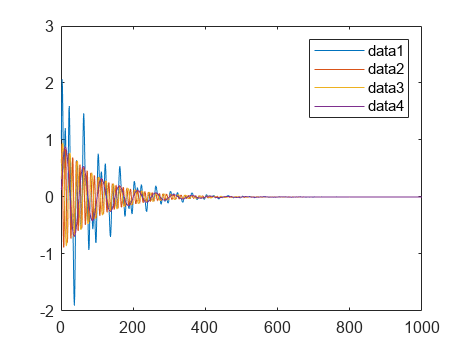

hankelSeries =     1.0120    1.7521    2.0653    1.9414    1.5103    0.9868    0.5860    0.4441    0.5722    0.8606    1.1297    1.2074    1.0011    0.5381   -0.0421   -0.5403   -0.7726   -0.6418   -0.1755    0.4812    1.1174    1.5304    1.5960    1.3091    0.7788    0.1835   -0.2983   -0.5528   -0.5691   -0.4354   -0.2976   -0.2957   -0.5049   -0.9026   -1.3749   -1.7589   -1.9051   -1.7349   -1.2723   -0.6375   -0.0053    0.4563    0.6437    0.5502    0.2628   -0.0748   -0.3189   -0.3787   -0.2476    0.0000
    1.7521    2.0653    1.9414    1.5103    0.9868    0.5860    0.4441    0.5722    0.8606    1.1297    1.2074    1.0011    0.5381   -0.0421   -0.5403   -0.7726   -0.6418   -0.1755    0.4812    1.1174    1.5304    1.5960    1.3091    0.7788    0.1835   -0.2983   -0.5528   -0.5691   -0.4354   -0.2976   -0.2957   -0.5049   -0.9026   -1.3749   -1.7589   -1.9051   -1.7349   -1.2723   -0.6375   -0.0053    0.4563    0.6437    0.5502    0.2628   -0.0748   -0.3189   -0.3787   -0.2476    

ar_model =
Discrete-time AR model: A(z)y(t) = e(t)                                                                            
  A(z) = 1 - 7.126 z^-1 + 22.99 z^-2 - 43.79 z^-3 + 53.84 z^-4 - 43.75 z^-5 + 22.95 z^-6 - 7.107 z^-7 + 0.9965 z^-8
                                                                                                                   
Sample time: 1 seconds
  
Parameterization:
   Polynomial orders:   na=8
   Number of free coefficients: 8
   Use "polydata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                                          
Estimated using AR ('fb/now') on time domain data "train_series".
Fit to estimation data: 100%                                     
FPE: 5.668e-11, MSE: 5.578e-11                                   
 


    "Prediction using full time series (no noise): -9.5476e-05"
    "Prediction using full time series (no noise): -9.9543e-05"
    "Prediction using full time series (no noise): -8.2706e-05"
    "Prediction using full time series (no noise): -4.6597e-05"
    "Prediction using full time series (no noise): 6.8875e-07"



    "Ground truth: -9.5479e-05"
    "Ground truth: -9.9563e-05"
    "Ground truth: -8.2793e-05"
    "Ground truth: -4.6871e-05"
    "Ground truth: 6.9033e-19"




%kunnen we dmv de values van V en die individueel gebruiken om het volgende
%punt te voorspelen mogelijk een betere voorspelling doen dan als we het
%gecombineerde gebruiken om het volgende punt te voorspellen?
figure; plot(V(:,1));
hold all; plot(V(:,2));
plot(V(:,3))

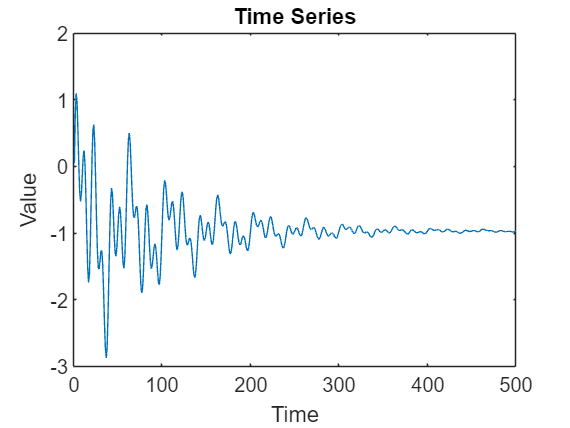

clear all;
format long;

% Parameters
N = 500;  % Number of points in the time series
num_predict = 1;
L = floor((N-1) / 2);
num_experiments = 100;  % Number of experiments to perform
optimal_order = 10;  % Set a fixed optimal order for simplicity

% Generate sinusoidal signals
t = (1:N)';

option = 3;

% Define base signals without decay and random addition
base_signal1 = sin(2 * pi * 0.1 * t);
base_signal2 = sin(2 * pi * 0.05 * t);
base_signal3 = sin(2 * pi * 0.02 * t);

% Apply selected option
switch option
    case 1
        % No decay or random addition
        signal1 = base_signal1;
        signal2 = base_signal2;
        signal3 = base_signal3;
    case 2
        % No random addition
        signal1 = base_signal1 .* exp(-0.01 * t);
        signal2 = base_signal2 .* exp(-0.01 * t);
        signal3 = base_signal3 .* exp(-0.01 * t);
    case 3
        % Everything (decay and random addition)
        signal1 = base_signal1 .* exp(-0.01 * t) + rand() * 10;
        signal2 = base_signal2 .* exp(-0.01 * t) - rand() * 10;
        signal3 = base_signal3 .* exp(-0.01 * t) + rand() * 10;
    otherwise
        error('Invalid option selected');
end

% Combine signals to form the time series
time_series = signal1 + signal2 + signal3;

% Plot the time series
figure;
plot(time_series);
title('Time Series');
xlabel('Time');
ylabel('Value');


% Ground truth for point 100
ground_truths = zeros(num_experiments,1);

% Prepare storage for predictions
predictions_full = zeros(num_experiments, 1);
predictions_components = zeros(num_experiments, 1);

% Visualize the singular values of the Hankel matrix
H2D = hankel(time_series(1:L), time_series(L:end-1));
[U, S, V] = svd(H2D, 'econ');
singular_values = diag(S);

rank(H2D)

ans =      7


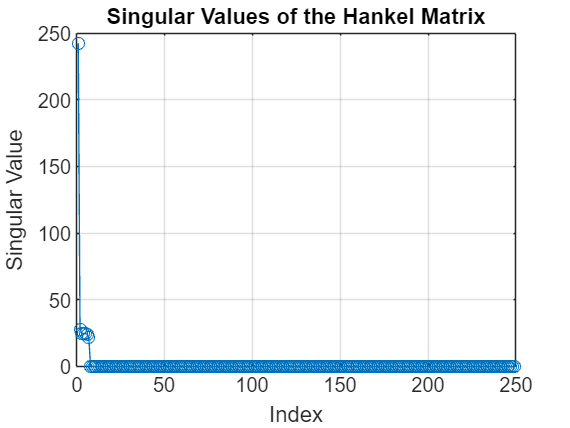

figure;
plot(singular_values, 'o-');
title('Singular Values of the Hankel Matrix');
xlabel('Index');
ylabel('Singular Value');
grid on;


rel_error_full = zeros(num_experiments,1);
rel_error_SVD = zeros(num_experiments,1);
norm_error_full = zeros(num_experiments,1);
norm_error_SVD = zeros(num_experiments,1);


% Perform the experiment
for exp = 1:num_experiments 
    if mod(exp,10)==0
        disp("iter "+exp);
    end
    % Add noise (for testing with noise, if needed)
    %noisy_series = time_series;  % No noise added in this case
    noisy_series = time_series+ randn(N, 1) * 0.1;  % No noise added in this case

    ground_truths(exp) = noisy_series(end);


    training_range = noisy_series(1:N-num_predict);
    
    % 1. Full time series prediction using AR model
    model_full = ar(noisy_series(1:N-1), optimal_order);  % AR(optimal_order) model
    pred_full = forecast(model_full, training_range, num_predict);
    predictions_full(exp) = pred_full(end);

    % 2. Decomposition using Hankel matrix (SVD)
    %H2Dzeros = hankel(noisy_series(1:N-1));
    H2Dzeros = hankel(noisy_series(1:L),noisy_series(L:end-1));
    [U, S, V] = svd(H2Dzeros, 'econ');    

    num_components = 7;
    c = zeros(L, N-L, num_components);
    pred_components = zeros(num_components, 1);

    
    figure;
    
    %plot(time_series)
    for comp = 1:num_components
        %tensor for holding all components (which are matrices)
        c(:,:,comp) = U(:,comp)*S(comp,comp)*V(:,comp)';

        % Convert component matrix back to time series by averaging along anti-diagonals
        component_series = zeros(N-1, 1);
        counts = zeros(N-1, 1);
        for i = 1:L
            for j = 1:(N-L)
                component_series(i+j-1) = component_series(i+j-1) + c(i,j,comp);
                counts(i+j-1) = counts(i+j-1) + 1;
            end
        end
        component_series = component_series ./ counts;


        %hold on;
        %plot(component_series);
        model_comp = ar(component_series, optimal_order);
        pred_comp = forecast(model_comp, component_series, num_predict);
        pred_components(comp) = pred_comp(end);
    end
    %legend({'Original', 'c1', 'c2', 'c3', 'c4', 'c5', 'c6', 'c7'});
    %hold off;

    predictions_components(exp) = sum(pred_components);

    rel_error_full(exp) = abs(predictions_full(exp)-ground_truths(exp))/abs(ground_truths(exp));
    rel_error_SVD(exp) = abs(predictions_components(exp)-ground_truths(exp))/abs(ground_truths(exp));
    norm_error_full(exp) = norm(predictions_full(exp),2)/norm(ground_truths(exp),2);
    norm_error_SVD(exp) = norm(predictions_components(exp),2)/norm(ground_truths(exp),2);
end

iter 10
iter 20
iter 30
iter 40
iter 50
iter 60
iter 70
iter 80
iter 90
iter 100



%{
% Compare predictions
figure;
subplot(2, 1, 1);
histogram(predictions_full);
title('Predictions from Full Time Series');
xlabel('Predicted Value');
ylabel('Frequency');
xline(ground_truths, 'r', 'LineWidth', 2);  % Ground truth line

subplot(2, 1, 2);
histogram(predictions_components);
title('Predictions from Component Decomposition (SVD)');
xlabel('Predicted Value');
ylabel('Frequency');
xline(ground_truths, 'r', 'LineWidth', 2);  % Ground truth line
%}

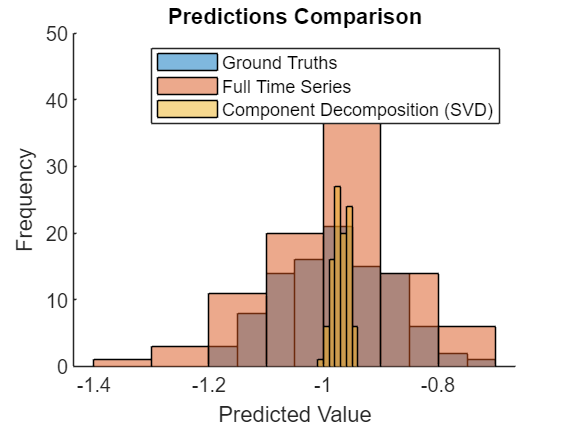

figure;
hold on;
histogram(ground_truths, 'FaceAlpha', 0.5, 'DisplayName', 'Ground Truths');
histogram(predictions_full, 'FaceAlpha', 0.5, 'DisplayName', 'Full Time Series');
histogram(predictions_components, 'FaceAlpha', 0.5, 'DisplayName', 'Component Decomposition (SVD)');
title('Predictions Comparison');
xlabel('Predicted Value');
ylabel('Frequency');
legend;
hold off;

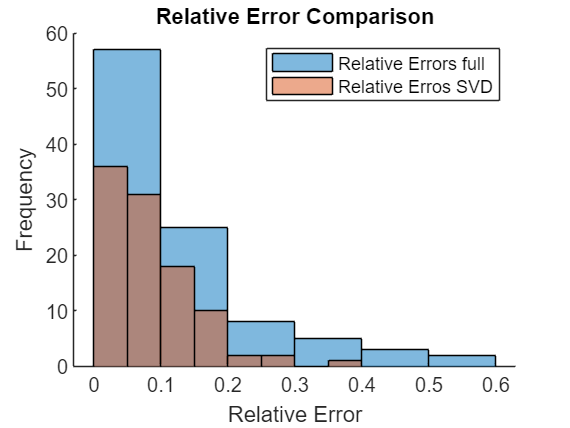


figure;
hold on;
histogram(rel_error_full, 'FaceAlpha', 0.5, 'DisplayName', 'Relative Errors full');
histogram(rel_error_SVD, 'FaceAlpha', 0.5, 'DisplayName', 'Relative Erros SVD');
%histogram(predictions_components, 'FaceAlpha', 0.5, 'DisplayName', 'Component Decomposition (SVD)');
title('Relative Error Comparison');
xlabel('Relative Error');
ylabel('Frequency');
legend;
hold off;

summary

% Display mean and standard deviation of predictions
disp('Full Time Series Predictions:');

Full Time Series Predictions:


disp("Mean: "+mean(predictions_full)+ ...
    ", SD: "+std(predictions_full)+ ...
    ", RMSE: "+rmse(predictions_full,ground_truths)+ ...
    ", MRE: "+mean(rel_error_full)+ ...
    ", MRSE: "+mean(norm_error_full));

Mean: -0.98231, SD: 0.10779, RMSE: 0.15394, MRE: 0.12243, MRSE: 1.0191



errors_full = [mean(predictions_full);std(predictions_full);rmse(predictions_full,ground_truths);mean(rel_error_full);mean(norm_error_full)];

disp('Component Decomposition Predictions (SVD):');

Component Decomposition Predictions (SVD):


disp("Mean: "+mean(predictions_components)+ ...
    ", SD: "+std(predictions_components)+ ...
    ", RMSE: "+rmse(predictions_components,ground_truths)+ ...
    ", MRE: "+mean(rel_error_SVD)+ ...
    ", MRSE: "+mean(norm_error_SVD));

Mean: -0.96957, SD: 0.013033, RMSE: 0.098838, MRE: 0.084064, MRSE: 1.0043



errors_SVD = [mean(predictions_components);std(predictions_components);rmse(predictions_components,ground_truths);mean(rel_error_SVD);mean(norm_error_SVD)];